# CALM CHARACTERIZATION

clear all
clc

load("C:\Users\mdilucchio\OneDrive - Fondazione Istituto Italiano Tecnologia\Desktop\CALM\" + ...
    "Materiale\PROGETTO CALM\Caratterizzazione CALM\Calibration_steps\pixels_to_world_coordinates\" + ...
    "improvement_test\calibrazione_720_576\dati di calibrazione\calm_camera_calibration.mat");

intrinsics = calm_camera_calibration.Instrinsics_params;
extrinsics = calm_camera_calibration.Extrinsics_params;

load("C:\Users\mdilucchio\OneDrive - Fondazione Istituto Italiano Tecnologia\Desktop\CALM\" + ...
    "Materiale\PROGETTO CALM\Caratterizzazione CALM\Calibration_steps\pixels_to_world_coordinates\" + ...
    "improvement_test\calibrazione_720_576\CameraCalibratorApp\cameraParams.mat");

Soggetto = 'Daniela'; trialID = "trial2";  targetID = 'quadrato'; vidout_on =  true;

% Percorso base
basePath = fullfile('C:\Users\mdilucchio\OneDrive - Fondazione Istituto Italiano Tecnologia\Desktop\CALM\Materiale\PROGETTO CALM\Caratterizzazione CALM\dati test\test_accuratezza_user', Soggetto);

% Estrai l'ultima parola di basePath
[~, baseName] = fileparts(basePath); % baseName sarà 'Enrico'

% Percorso completo del video
videoPath = fullfile(basePath, trialID, targetID, [Soggetto '_' targetID '_' char(trialID) '.mpg']);

% Estrai il percorso senza l'ultimo elemento
[folder_target, ~, ~] = fileparts(videoPath);

% Lettura del video
video = VideoReader(videoPath);

% Parametri per l'elaborazione video
frames_number = video.NumFrames

frames_number = 2266

frame_rand = randi([0,frames_number])

frame_rand = 1433

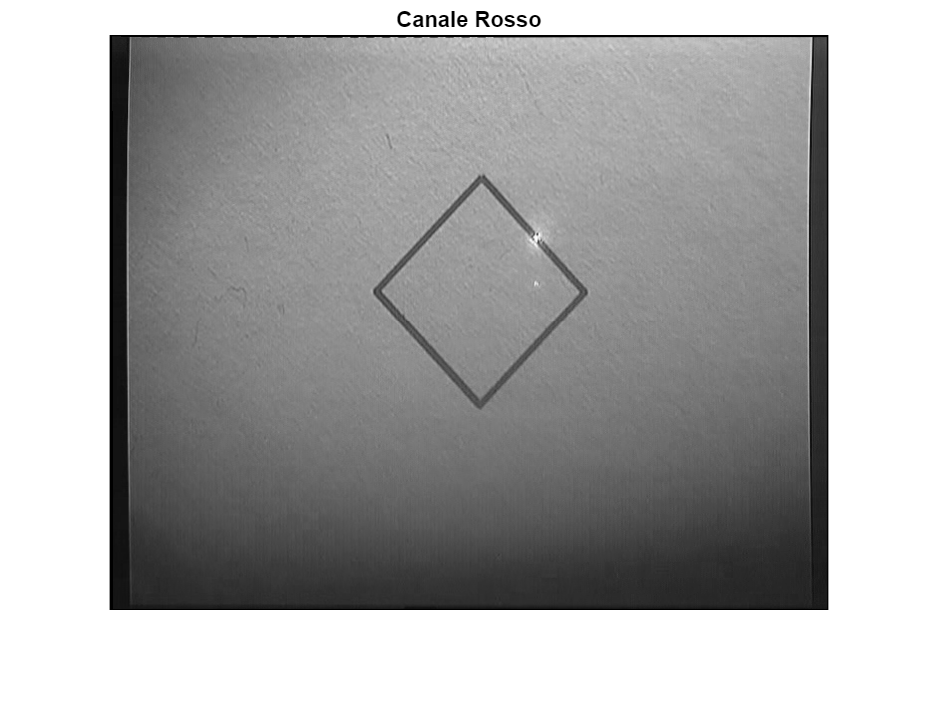

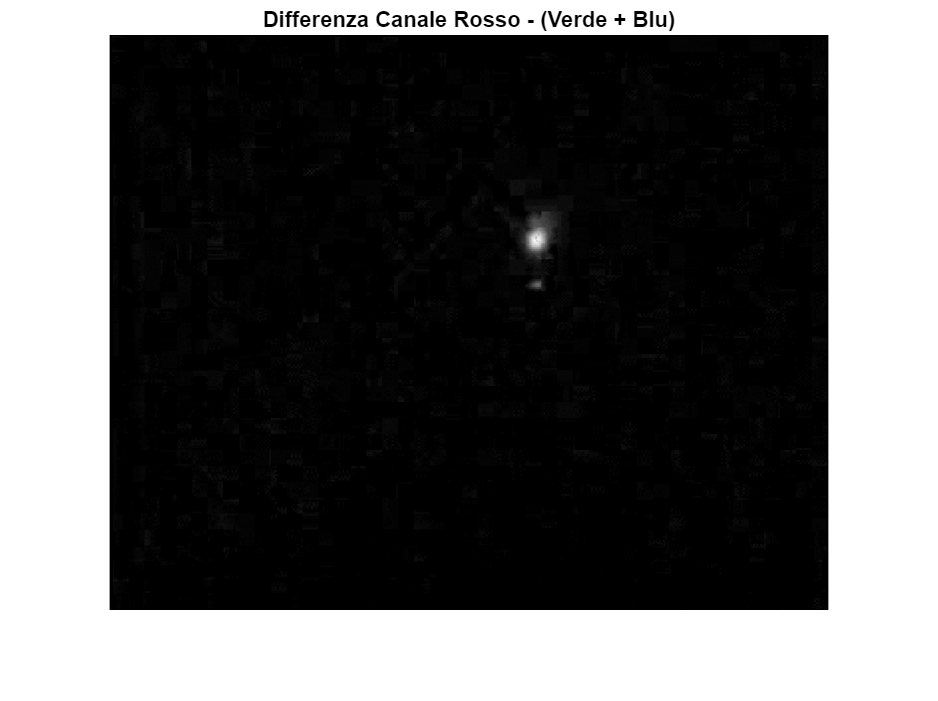

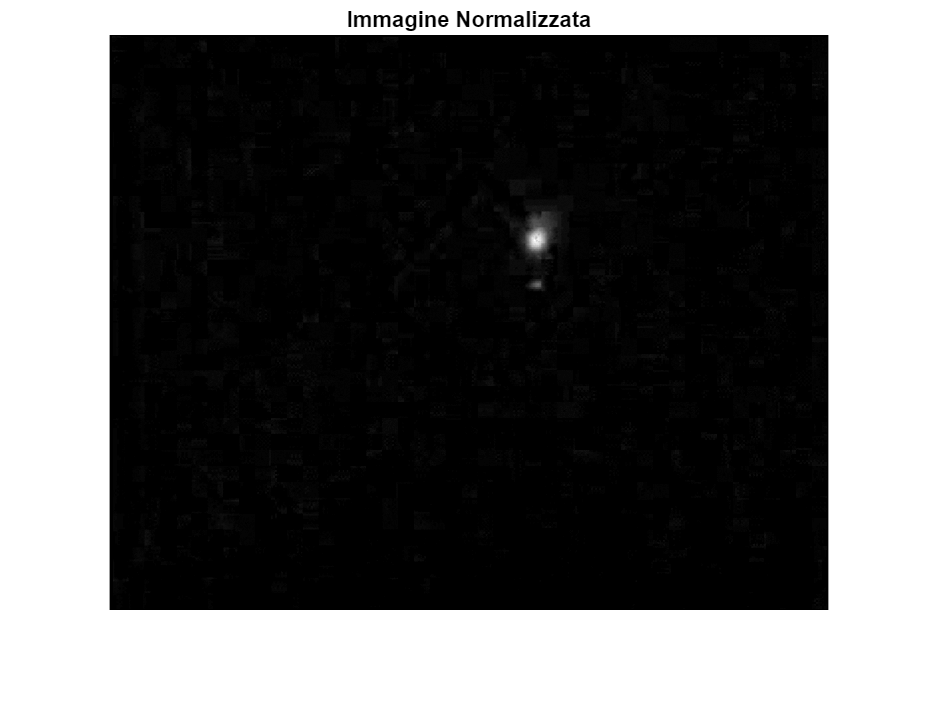

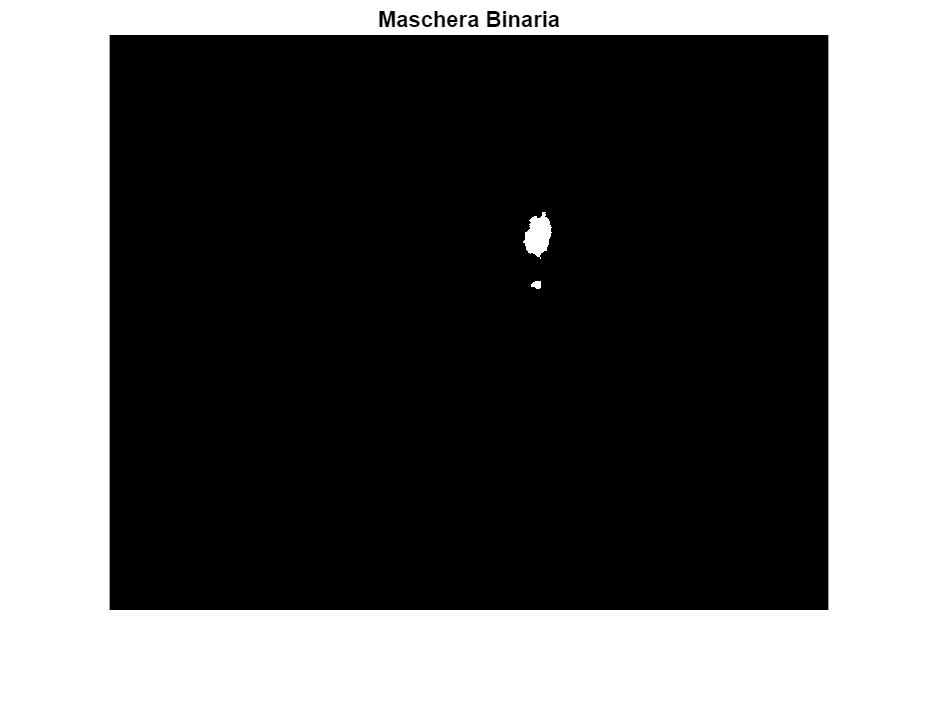

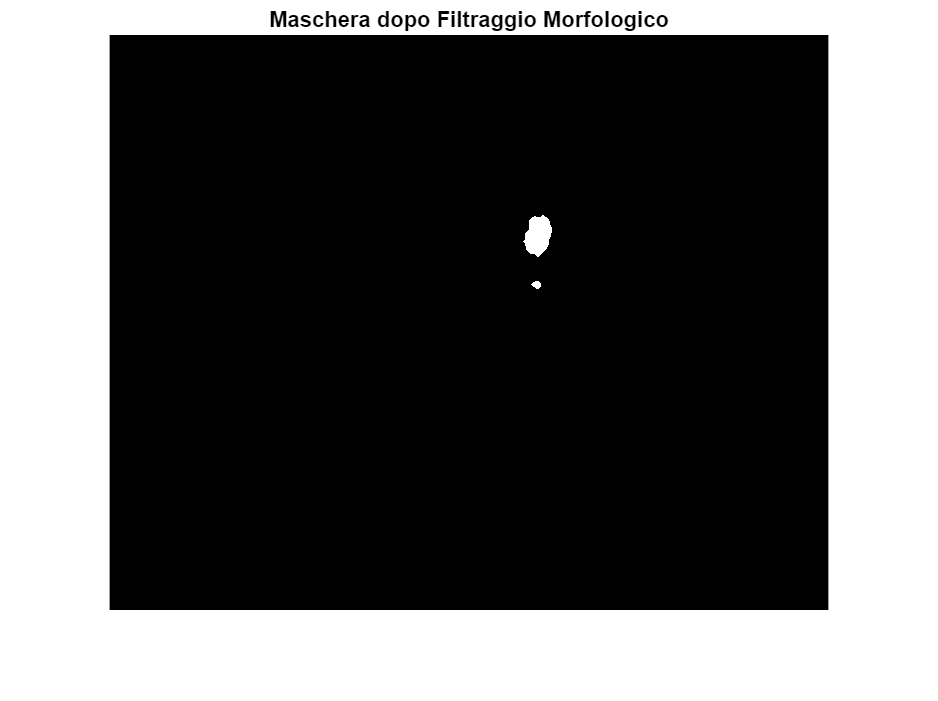

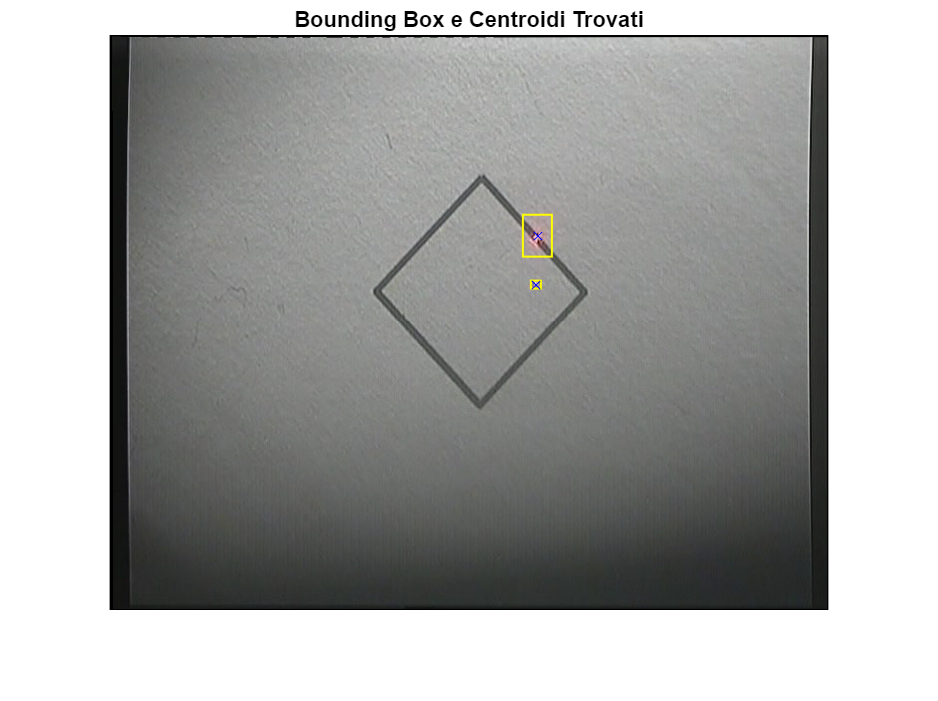

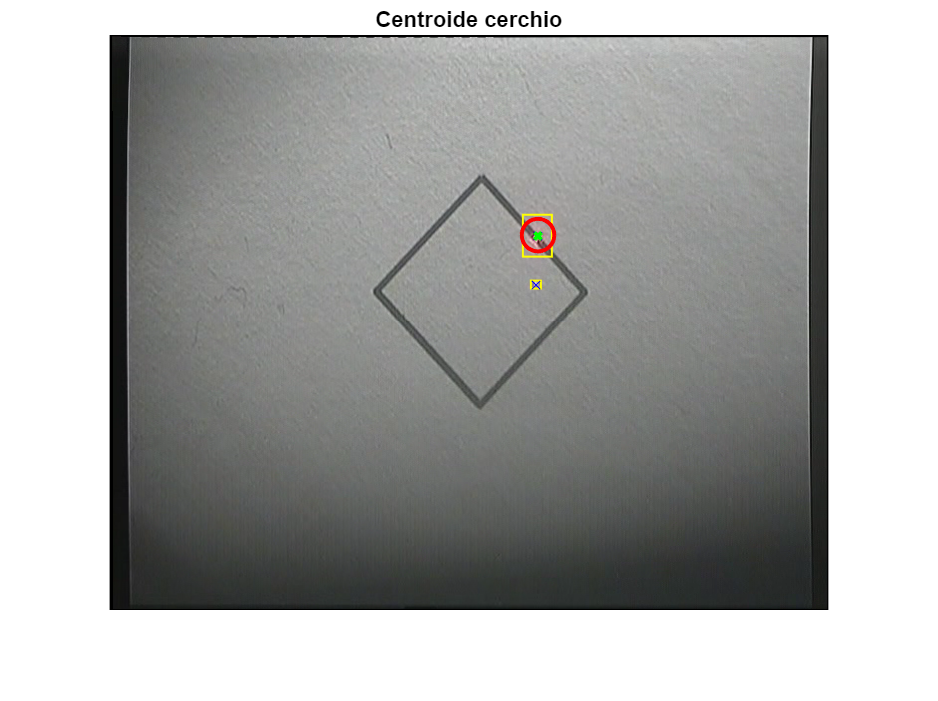

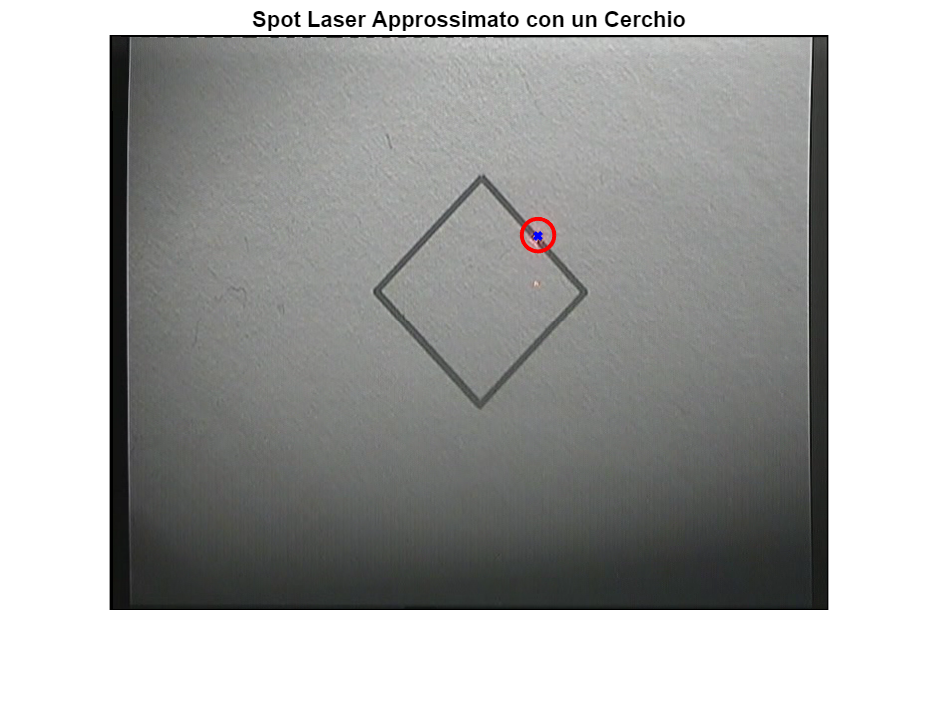

fps_out = 25;

% Creazione di video_name con il file modificato
processedFileName = [Soggetto '_' targetID '_' char(trialID) '_processed.mpg'];
video_name = fullfile(folder_target, processedFileName);

if vidout_on
    writerObj = VideoWriter([char(video_name), '.mp4'], 'MPEG-4');
    writerObj.FrameRate = fps_out;
    open(writerObj);
end

% Preallocazione matrice per traiettoria
coords_matrix = NaN(video.NumFrames, 3); % Colonne e righe
trajectory_mask = zeros(video.Height, video.Width); % Maschera accumulativa per la traiettoria

frame_index = 0; % Indice del frame corrente

problematic_frame_indices = []; % Lista per i frame in cui lo spot non è stato rilevato

% Loop per analizzare e tracciare ogni frame
while hasFrame(video)

    frame_index = frame_index + 1;

    try
        
        % Leggi e correggi il frame
        frame = readFrame(video); % Leggi il frame corrente. frame is an H x W x B matrix where:
        %  H is the image frame height
        %  W is the image frame width
        %  B is the number of bands in the image (e.g. 3 for RGB)
        [frame_Undist, frameIntrinsics] = undistortImage(frame, cameraParams);

        % Esegui il rilevamento dello spot laser (coordinate in pixels)
        if (frame_index == frame_rand)
            coords = spot_detector(frame_Undist, 1, 1);
        else
            coords = spot_detector(frame_Undist, 0, 0);
        end


        if ~isnan(coords.row) && ~isnan(coords.col)
            row = round(coords.row);
            col = round(coords.col);

            % Aggiorna matrice e maschera
            coords_matrix(frame_index, :) = [frame_index, col, row];
            trajectory_mask(row, col) = 1;

            % Disegna il cerchio sul punto corrente
            frame_Undist = insertShape(frame_Undist, 'FilledCircle', [col, row, 5], 'Color', 'green', 'Opacity', 1);

            % Disegna le linee guida
            color = 180; % Grigio
            frame_Undist(row, :, 1) = color; % Linea orizzontale (R)
            frame_Undist(row, :, 2) = color; % Linea orizzontale (G)
            frame_Undist(row, :, 3) = color; % Linea orizzontale (B)

            frame_Undist(:, col, 1) = color; % Linea verticale (R)
            frame_Undist(:, col, 2) = color; % Linea verticale (G)
            frame_Undist(:, col, 3) = color; % Linea verticale (B)

        else
            % Spot laser non rilevato
            problematic_frame_indices = [problematic_frame_indices, frame_index];
            fprintf('Spot non rilevato nel frame %d\n', frame_index);
        end

        % Sovrapposizione della traiettoria
        [rows, cols] = find(trajectory_mask);
        for k = 1:length(rows)
            frame_Undist(rows(k), cols(k), :) = [0, 255, 0]; % Verde
        end

        % Scrivi il frame processato nel file video
        if vidout_on
            writeVideo(writerObj, frame_Undist);
        end

        catch ME
        fprintf('Errore nel frame %d: %s\n', frame_index, ME.message);
        continue; % Salta il frame problematico
    end

end

% Chiudi il file video
if vidout_on
    close(writerObj);
end

if ~isempty(problematic_frame_indices)
    fprintf('Frame problematici: %s\n', num2str(problematic_frame_indices));

    % Identifica le righe con valori NaN in colonna 2 o 3
    rows_with_nan = isnan(coords_matrix(:, 2)) | isnan(coords_matrix(:, 3));

    % Elimina queste righe dalla matrice
    coords_matrix(rows_with_nan, :) = [];

else
    fprintf('Tutti i frame processati correttamente.\n');
end

Tutti i frame processati correttamente.


## Check Trajectory

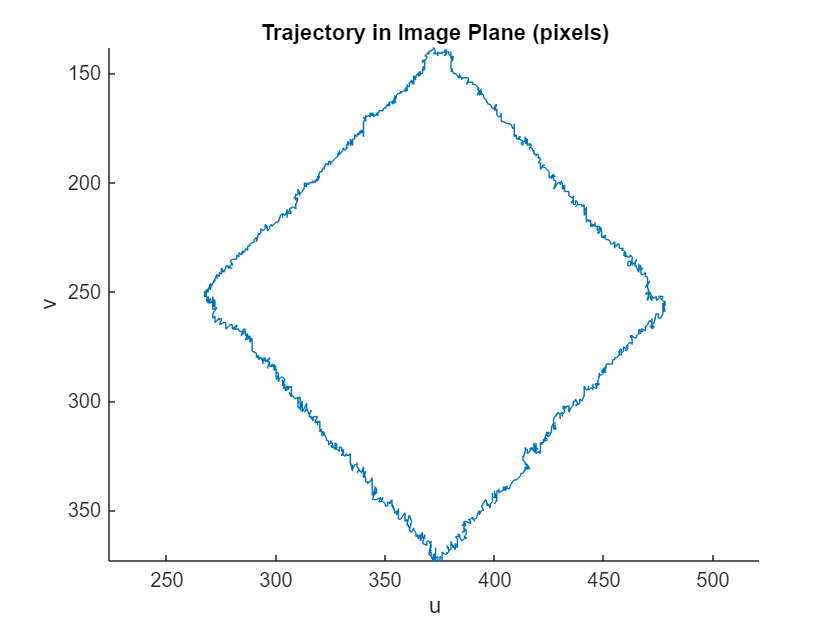

figure
plot(coords_matrix(:,2), coords_matrix(:,3))
xlabel 'u'
ylabel 'v'
title('Trajectory in Image Plane (pixels)')
box off
axis equal
set(gca, 'YDir', 'reverse'); % Invertiamo l'asse Y per riflettere il piano mondo

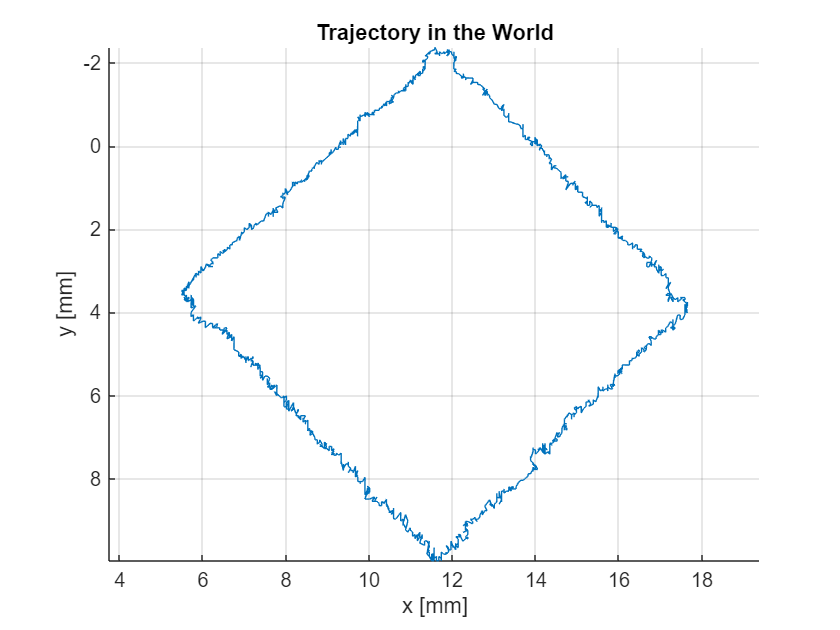

laserWorldPoints = zeros(length(coords_matrix), 2);
 
for i = 1:length(coords_matrix)

    laserWorldPoints(i,:) = img2world2d(coords_matrix(i,2:3), extrinsics, intrinsics); % millimetri

end

% Plot della traiettoria nel mondo
figure
plot(laserWorldPoints(:,1), laserWorldPoints(:,2));
hold on
set(gca, 'YDir', 'reverse'); % Invertiamo l'asse Y per riflettere il piano mondo
xlabel 'x [mm]'
ylabel 'y [mm]'
axis equal;
grid on;

title('Trajectory in the World')
box off

## Analisi in frequenza per la rimozione del ripple

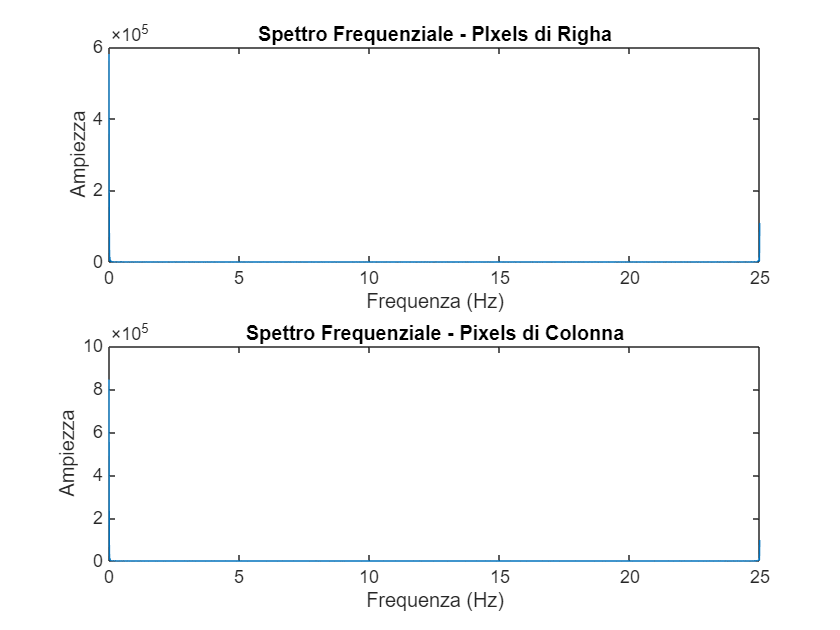

% Analisi in frequenza per rimuovere il ripple dalle coordinate del laser
% frame_rate: Frequenza di campionamento (25 Hz)
% cutoff_frequency: Frequenza di taglio del filtro passa-basso (in Hz)

% Calcola la Trasformata di Fourier delle coordinate
N = length(coords_matrix(:,2));
Fs = video.FrameRate;  % Frequenza di campionamento (25 Hz)

% Trasformata di Fourier (DFT)
F_row = fft(coords_matrix(:,3));
F_col = fft(coords_matrix(:,2));

% Frequenze associate a ciascun punto nella DFT
f = (0:N-1)*(Fs/N);  % Frequenze di Nyquist

% Spettro di ampiezza
figure;
subplot(2, 1, 1);
plot(f, abs(F_row));
title('Spettro Frequenziale - PIxels di Righa');
xlabel('Frequenza (Hz)');
ylabel('Ampiezza');

subplot(2, 1, 2);
plot(f, abs(F_col));
title('Spettro Frequenziale - Pixels di Colonna');
xlabel('Frequenza (Hz)');
ylabel('Ampiezza');

## Filtered Trajectory

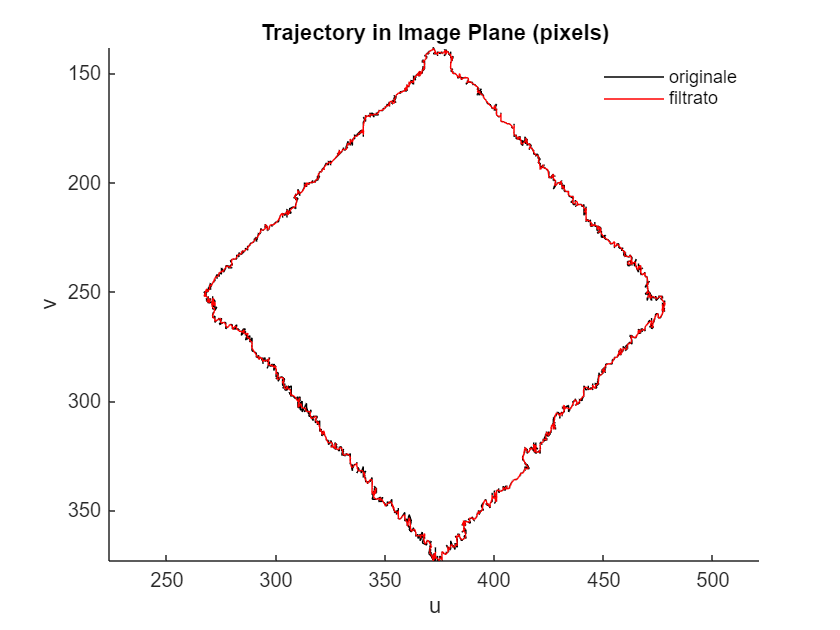

% Parametri del filtro passa-basso
cutoff_freq = 6; % Frequenza di taglio in Hz
[b, a] = butter(4, cutoff_freq / (Fs / 2), 'low'); % Filtro Butterworth: cutoff_freq / (Fs / 2) normalizza la frequenza di taglio rispetto alla frequenza di Nyquist (che è Fs/2 = 12.5Hz)

% Applica il filtro passa-basso con filtfilt
filtered_row = filtfilt(b, a, coords_matrix(:,3));
filtered_col = filtfilt(b, a, coords_matrix(:,2));

% Plotta il confronto
figure;
hold on;
plot(coords_matrix(:,2), coords_matrix(:,3), 'k', 'DisplayName', 'Originale'); % Segnale originale
plot(filtered_col, filtered_row, 'r', 'DisplayName', 'Filtrato (filtfilt)'); % Segnale filtrato
legend('originale', 'filtrato');
legend box off
xlabel 'u'
ylabel 'v'
axis equal;
title('Trajectory in Image Plane (pixels)')
box off
set(gca, 'YDir', 'reverse'); % Invertiamo l'asse Y per riflettere il piano mondo

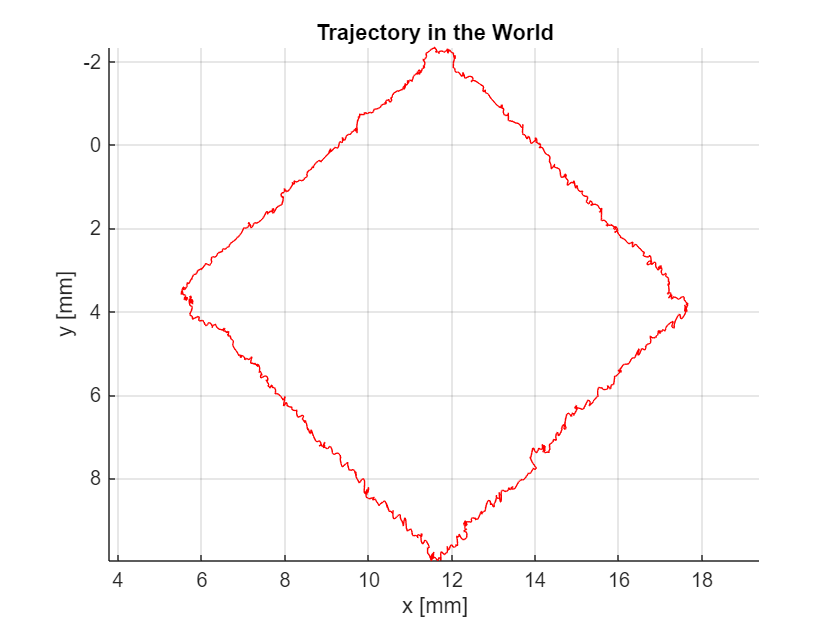

coords_matrix_filtered = [filtered_col, filtered_row];

for i = 1:length(coords_matrix_filtered)

    laserWorldPoints_filtered(i,:) = img2world2d(coords_matrix_filtered(i,1:2), extrinsics, intrinsics); % millimetri

end

% Plot della traiettoria nel mondo
figure
% plot(laserWorldPoints(:,1), laserWorldPoints(:,2),'b');
hold on
plot(laserWorldPoints_filtered(:,1), laserWorldPoints_filtered(:,2),'r');
% legend('Original', 'Filtered')
% legend box off
xlabel 'x [mm]'
ylabel 'y [mm]'
axis equal;
grid on;
set(gca, 'YDir', 'reverse'); % Invertiamo l'asse Y per riflettere il piano mondo
title('Trajectory in the World')
box off

## SALVA I DATI

% Salvo ogni variabile con il rispettivo nome nel folder 
variabili = {'coords_matrix', 'laserWorldPoints', 'laserWorldPoints_filtered'};
for i = 1:numel(variabili)
    varName = variabili{i};
    fileName = fullfile(folder_target, [varName, '.mat']);
    save(fileName, varName);
end

## CONFRONTO CON IL TARGET

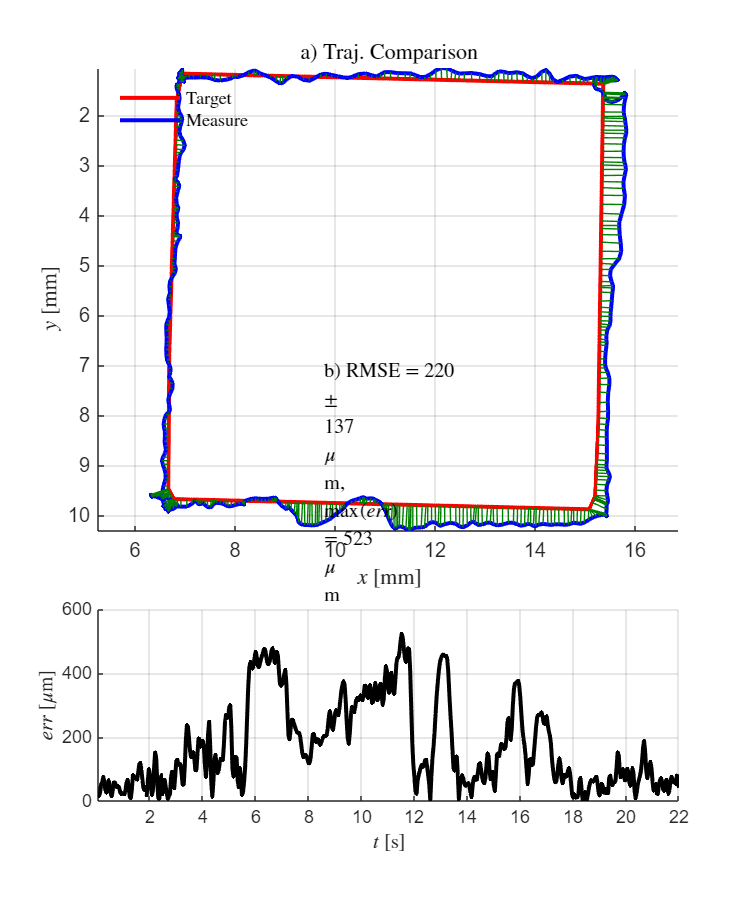

RMSE     = 220 ± 137 µm
max(err) = 523 µm


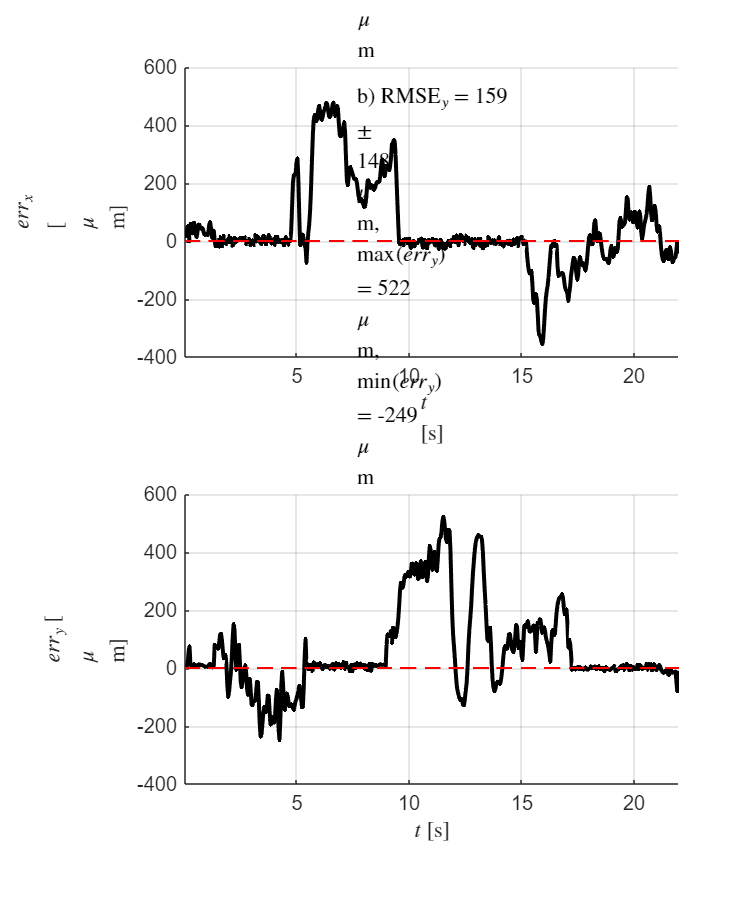

% Percorso completo della directory dove si trova il file
fileDirectory  = fullfile(basePath, trialID, targetID);

% Percorso completo al file TargetWorldCoordinates.mat
targetFile = fullfile(fileDirectory, 'TargetWorldCoordinates.mat');
laserFile = fullfile(fileDirectory, 'laserWorldPoints_filtered.mat');
laserFile_coords_matrix = fullfile(fileDirectory, 'coords_matrix.mat');

% Caricamento del file
target = load(targetFile);
laser = load(laserFile);
laser_coords_matrix = load(laserFile_coords_matrix);

% t is time
% t = (1:1:length(laser_coords_matrix.coords_matrix(:,2)))'/ video.FrameRate;
t = (1:1:length(laser.laserWorldPoints_filtered(:,2)))'/ video.FrameRate;


x_target = target.TargetWorldCoordinates(:,1);
y_target = target.TargetWorldCoordinates(:,2);
x_laser = laser.laserWorldPoints_filtered(:,1);
y_laser = laser.laserWorldPoints_filtered(:,2);

[rmse, rmse_x, rmse_y, std_f, std_x ,std_y, figHandles] = circ_rmse(x_target, y_target, x_laser, y_laser, t, 1);

rmse_tot = rmse;
std_tot = std_f;
rmse_x = rmse_x;
std_x = std_x;
rmse_y = rmse_y;
std_y = std_y;

data = [rmse_tot, std_tot; rmse_x, std_x; rmse_y, std_y]

data =   219.5909  136.6367
    0.1512    0.1445
    0.1592    0.1478


fileName = fullfile(folder_target,'data.mat');
save(fileName, 'data');

% Salva solo le figure generate dalla funzione
names = {'Taj_Comparison.fig', 'Axis_Errors.fig'};
for i = 1:numel(figHandles)
    fig = figHandles(i);
    % File name per ciascuna figura
    % figFileName = fullfile(folder, sprintf('CircRMSE_Figure_%d.fig', i));
    figFileName = fullfile(folder_target, sprintf(names{i}));

    % Salva il file .fig
    savefig(fig, figFileName);
    
end